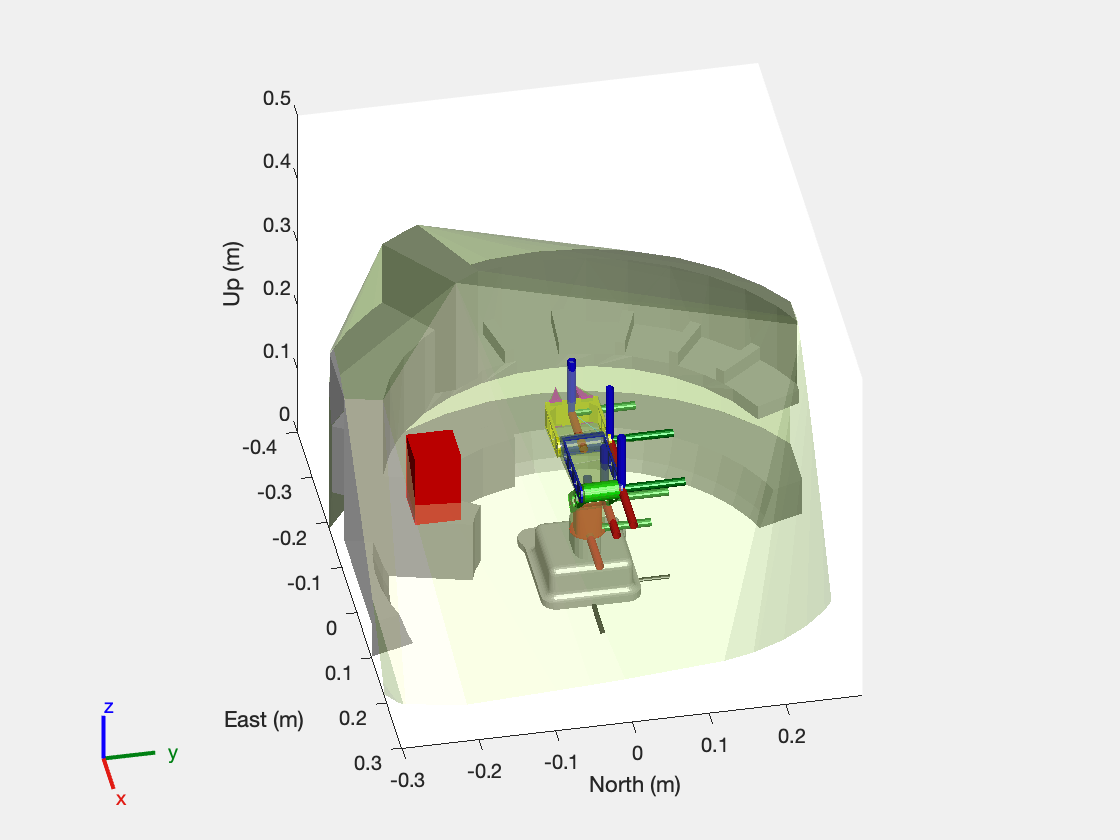

% Perform Pick and Place in Robot Scenario
clc
clear

% Create a robotScenario object.
scenario = robotScenario(UpdateRate=10, StopTime=10);

% Load in the correct file directory
addpath("/Users/louieburns/Library/CloudStorage/OneDrive-UniversityofLeeds/Robotics Coursework/URDFs/Robot_URDF/urdf")  % Louie Path folder
% addpath("C:\Users\dnehu\OneDrive - University of Leeds\Robotics Coursework\URDFs\Robot_URDF\urdf")  % Dan path folder
savepath % Save filepath for next time

% Create a rigidBodyTree object of the Franka Emika Panda manipulator using loadrobot.
robotRBT = importrobot("Robot_URDF.urdf");
robotRBT.DataFormat = 'row';  % Set data format explicitly for collision checking

% Create a rigidBodyTree-based robotPlatform object using the manipulator model.
robot = robotPlatform("Manipulator", scenario, ...
                      RigidBodyTree=robotRBT);

% Create a non-rigidBodyTree-based robotPlatform object of a box to manipulate.
% Specify the mesh type and size.
box1_pos = [0 -0.2 0.2];

box = robotPlatform("Box", scenario, ...
                    Collision="mesh", ...
                    InitialBasePosition=box1_pos);

updateMesh(box, "Cuboid", Collision="mesh", Size=[0.06 0.06 0.1])

% Visualize the scenario.
ax = show3D(scenario, Collisions="on");
view(79,36)
axis equal
axis manual
xlim([-0.4 0.3]);
ylim([-0.3 0.3]);
zlim([0 0.5]);
light


% Inverse Kinematics
function q = analyticalIK(x, y, z)
    % Link lengths
    L1 = 0.107;
    L2 = 0.109;
    L3 = 0.072;
    L4 = 0.102;  % Wrist + claw offset
    baseHeight = 0.09;  % from robot base (35+55mm)

    % Step 1: Waist rotation
    theta1 = atan2(y, x);
    r = sqrt(x^2 + y^2);
    z = z - baseHeight;
    r = r - L4;  % Remove wrist offset

    % Step 2: Elbow angle using cosine law
    D = (r^2 + z^2 - L1^2 - L2^2) / (2 * L1 * L2);
    if abs(D) > 1
        error("Position unreachable");
    end
    theta3 = atan2(sqrt(1 - D^2), D);  % Elbow-down config

    % Step 3: Shoulder angle
    phi = atan2(z, r);
    psi = atan2(L2 * sin(theta3), L1 + L2 * cos(theta3));
    theta2 = phi - psi;

    % Step 4: Wrist angle
    theta4 = - (theta2 + theta3);

    % Step 5: Return joint angles
    q = [theta1, theta2, theta3, theta4];
end

% Example target position (position of the box)
targetPos = [box1_pos(1), -box1_pos(2), box1_pos(3)];
q = analyticalIK(targetPos(1), targetPos(2), targetPos(3));

% Get initial and target joint configurations
initialStruct = homeConfiguration(robotRBT);
initialConfig = zeros(1, numel(initialStruct));
for i = 1:numel(initialStruct)
    initialConfig(i) = initialStruct(i).JointPosition;
end

Dot indexing is not supported for variables of this type.


targetConfig = initialConfig;
targetConfig(1:4) = q;
targetConfig(5) = -0.015;
targetConfig(6) =  0.015;

% Interpolate smoothly (ease-in and ease-out) and check for collisions
steps = 50;
t_vals = linspace(0,1,steps);
t_ease = 0.5 - 0.5*cos(pi*t_vals);  % ease-in, ease-out interpolation

for idx = 1:steps
    t = t_ease(idx);
    interpConfig = (1 - t) * initialConfig + t * targetConfig;

    show(robotRBT, interpConfig, FastUpdate=true, PreservePlot=false);
    title("Analytical IK: Grasping Box");
    axis equal
    axis manual
    xlim([-0.4 0.3]);
    ylim([-0.3 0.3]);
    zlim([0 0.5]);

    % Collision checking
    isColliding = checkCollision(robotRBT, interpConfig, 'SkippedSelfCollisions', 'parent');
    if isColliding
        disp('Collision detected!');
        break;
    end

    drawnow;
end
